Warming up camera...
Processed frame 1/5
Processed frame 2/5
Processed frame 3/5
Processed frame 4/5
Processed frame 5/5
Camera stopped. Processing final frame for Blue Objects...


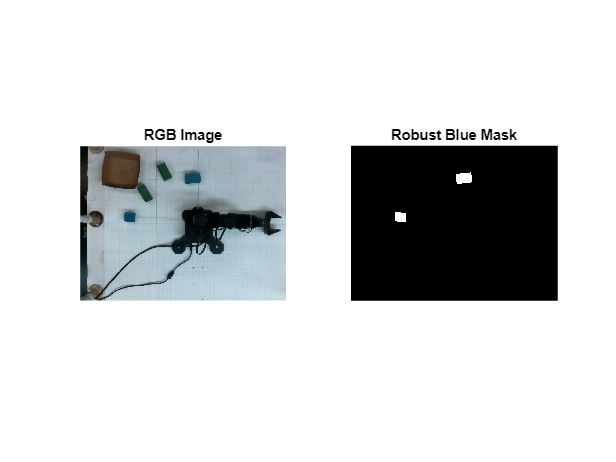

Clustering Point Cloud to remove noise...

--- TARGET DETECTED (Clustered) ---
Camera X: 0.040 m
Camera Y: -0.151 m
Camera Z: 0.682 m
-----------------------------------



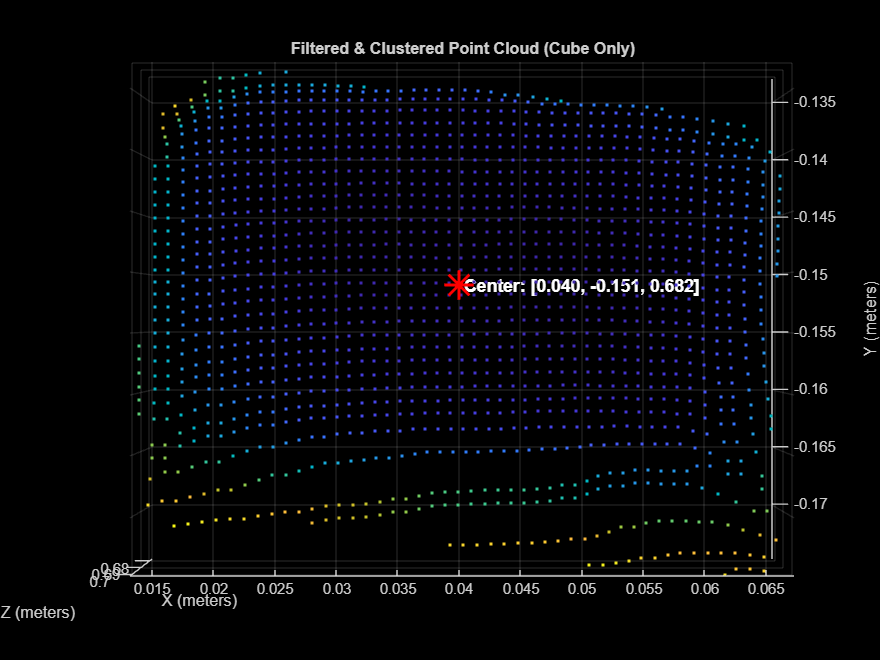

  perception_pipeline_3d_regionprops()

Initializing Camera...
Capturing frame...
Camera stopped. Processing image...
Labeled Object 1 at Camera XYZ: [1.019, -0.104, 0.661]
Labeled Object 2 at Camera XYZ: [1.545, 0.095, 0.656]
Labeled Object 3 at Camera XYZ: [0.000, 0.000, 0.000]
Screenshot complete!


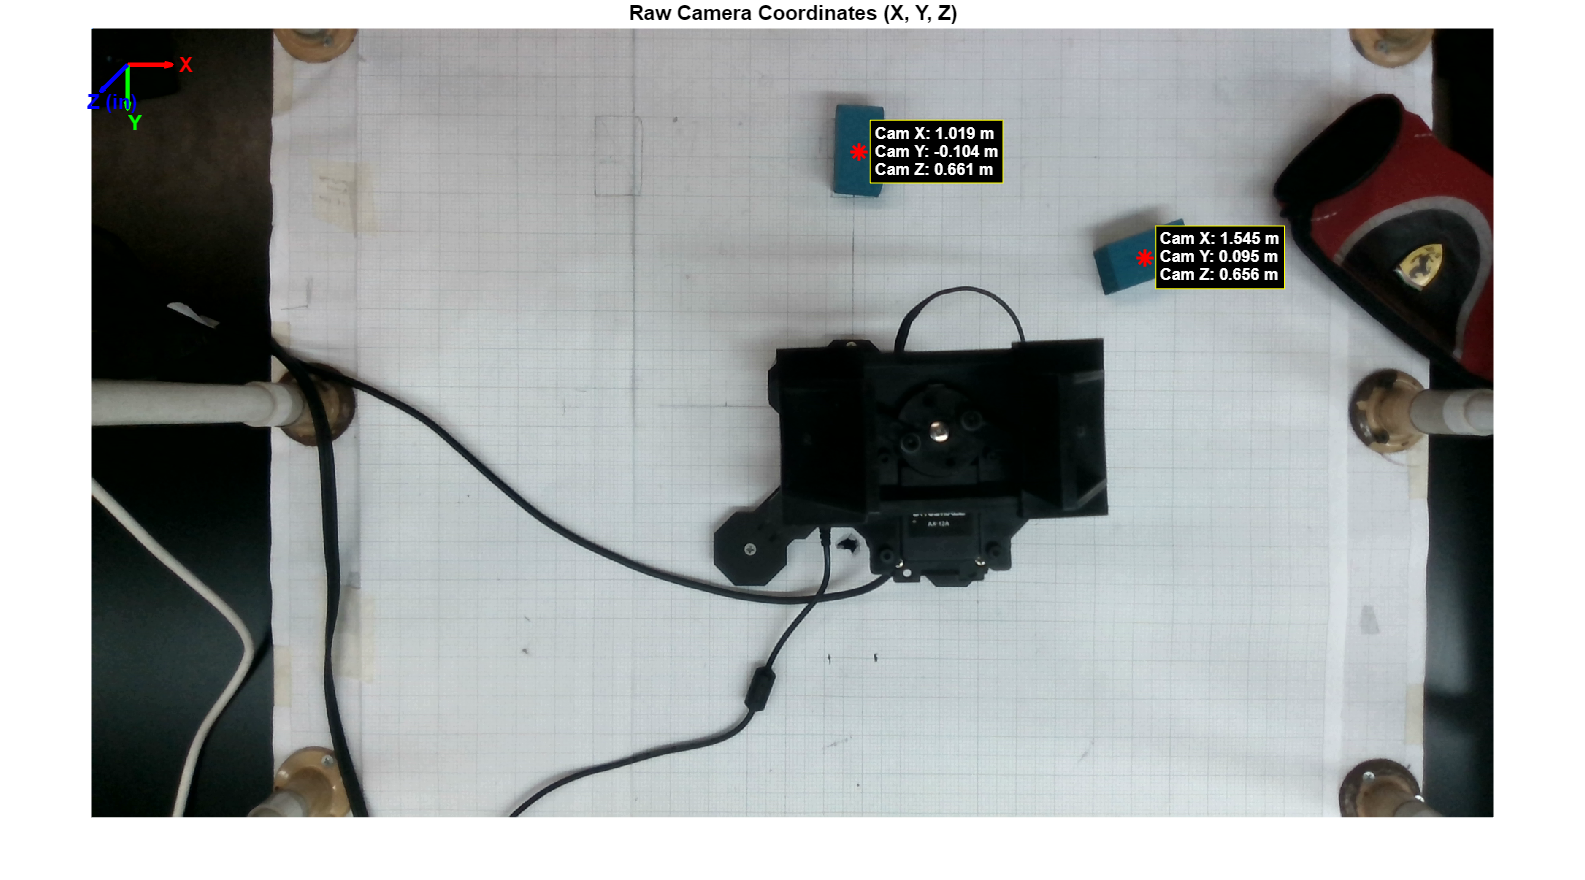

take_labeled_screenshot()

% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams (Note: Changed bgr8 to rgb8 for easier MATLAB color processing)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();

% Create align object to ensure depth perfectly matches color pixels
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


i = 0;
while i < 5
    % Wait for frames
    fs = pipe.wait_for_frames();
    
    % Align frames so depth and color pixels correspond 1:1
    fs = align_to_color.process(fs);
    
    % Get depth frame
    depth_frame = fs.get_depth_frame();
    
    % Get color frame
    color_frame = fs.get_color_frame();
    
    i = i + 1;
    
    % Map pointcloud to color and calculate points
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    
    % Get vertices natively
    vtx = points.get_vertices();
    
    fprintf('Processed frame %d/5\n', i);
end

Processed frame 1/5
Processed frame 2/5
Processed frame 3/5
Processed frame 4/5
Processed frame 5/5



% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame for Blue Objects...');

Camera stopped. Processing final frame for Blue Objects...


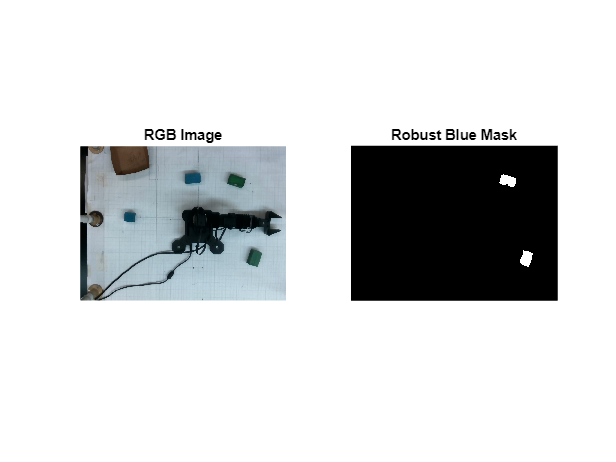


%% --- Extract RGB Image ---
% Pull raw data from the RealSense frame and reshape it into a standard MATLAB Image matrix
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

%% --- 2D HSV Color Segmentation (BLUE) ---
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); 
S = hsvI(:,:,2); 
V = hsvI(:,:,3);

% % 1. BLUE COLOR THRESHOLDS
% % Slightly widened Hue, but much stricter Saturation and Value (Brightness)
% hueMask = (H > 0.52) & (H < 0.65); 
% level = max(graythresh(S), 0.40); 
% mask = hueMask & (S > level) & (V > 0.25); 

% GREEN COLOR THRESHOLDS
hueMask = (H > 0.24) & (H < 0.475);
level = max(graythresh(S), 0.20);
mask = hueMask & (S > level) & (V > 0.185);

% Clean up the mask (remove noise, fill holes)
mask = bwareaopen(mask, 100); 
mask = imfill(mask, 'holes');

% 2. GEOMETRIC FILTERING (The "Robust" Fix)
% Analyze the remaining white blobs for their physical properties
stats = regionprops(mask, 'Area', 'PixelIdxList', 'Solidity');

% Create a blank mask to hold our geometrically filtered results
robust_mask = false(size(mask));

for j = 1:length(stats)
    % Filter Conditions:
    % - Area > 300: Must be larger than background noise specks
    % - Area < 15000: Must be smaller than massive objects (like a robot base)
    % - Solidity > 0.80: Must be a solid shape (cubes are highly solid)
    if stats(j).Area > 300 && stats(j).Area < 15000 && stats(j).Solidity > 0.80
        % If it passes the geometry test, keep it!
        robust_mask(stats(j).PixelIdxList) = true;
    end
end

% Overwrite the old mask with our new robust mask
mask = robust_mask;

% Show the 2D mask to verify it found ONLY the cube
figure('Name', 'Blue Detection Mask');
subplot(1,2,1); imshow(I); title('RGB Image');
subplot(1,2,2); imshow(mask); title('Robust Blue Mask');

Clustering Point Cloud to remove noise...



--- TARGET DETECTED (Clustered) ---


Camera X: 0.188 m


Camera Y: -0.141 m


Camera Z: 0.677 m


-----------------------------------




--- WORLD COORDINATES ---


World X: 141.040 mm


World Y: -138.010 mm


World Z: -0.677 m


-------------------------



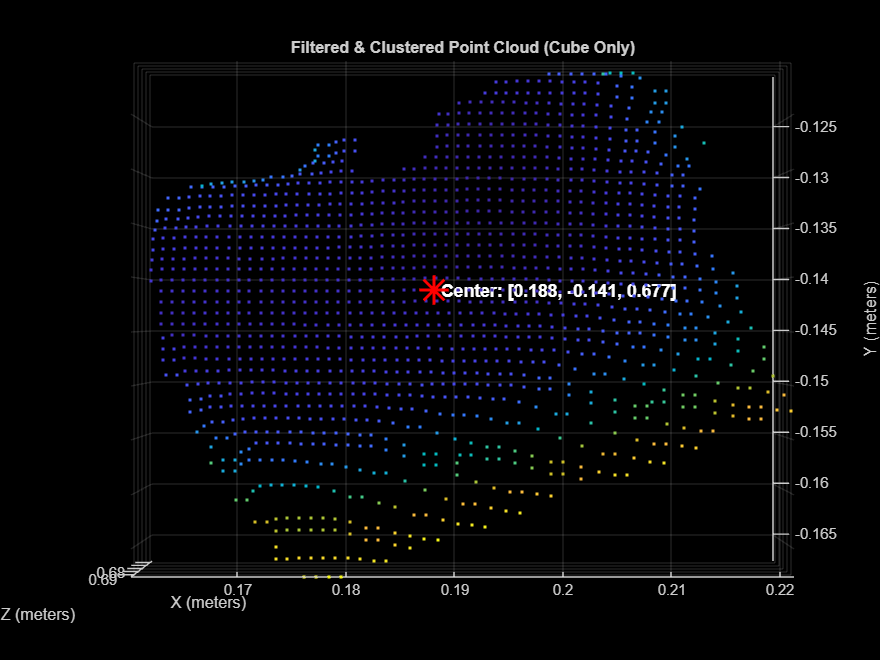


%% --- Filter the Point Cloud ---
% The 'vtx' matrix is 307200x3 (which is 640 * 480). 
% It stores points row-by-row. We need to flatten our 2D mask to match this order.
mask_1d = reshape(mask', [], 1);

% 1. Filter out points where the sensor read 0 depth
valid_depth = (vtx(:,3) > 0); 

% 2. Combine depth filter with our Blue mask filter
blue_indices = valid_depth & mask_1d;

% 3. Extract only the vertices that are Blue
blue_vtx = vtx(blue_indices, :);

if isempty(blue_vtx)
    disp('No blue objects found in the 3D space!');
else
    disp('Clustering Point Cloud to remove noise...');
    
    % Create a MATLAB pointCloud object using the blue vertices
    ptCloud = pointCloud(blue_vtx);
    
    % --- THE FIX: Cluster the points to remove floating noise ---
    % Group points that are within 3cm (0.03m) of each other
    [labels, numClusters] = pcsegdist(ptCloud, 0.008);
    
    if numClusters == 0
        disp('Could not find a distinct physical object.');
        return;
    end
    
    % Find the largest dense cluster (assuming the biggest blue thing is our cube)
    clusterSizes = zeros(numClusters, 1);
    for c = 1:numClusters
        clusterSizes(c) = sum(labels == c);
    end
    [~, biggestClusterIdx] = max(clusterSizes);
    
    % Extract ONLY the points belonging to the biggest cluster (the actual cube)
    cubeIndices = find(labels == biggestClusterIdx);
    cubeCloud = select(ptCloud, cubeIndices);
    
    % --- Calculate the centroid of ONLY the clustered cube ---
    pos_cam = mean(cubeCloud.Location, 1);
    
    % Print the coordinates to the command window
    fprintf('\n--- TARGET DETECTED (Clustered) ---\n');
    fprintf('Camera X: %.3f m\n', pos_cam(1));
    fprintf('Camera Y: %.3f m\n', pos_cam(2));
    fprintf('Camera Z: %.3f m\n', pos_cam(3));
    fprintf('-----------------------------------\n\n');

    % 1. Define the corrected 4x4 transformation matrix
    T_world_camera = [ 0 -1  0  0;
                      -1  0  0  0.05;
                       0  0 -1  0;
                       0  0  0  1];
    
    % 2. Convert pos_cam into a 4x1 homogeneous column vector: [x; y; z; 1]
    pos_cam_homog = [pos_cam(1); pos_cam(2); pos_cam(3); 1];
    
    % 3. Multiply to get the position in the world frame
    pos_world_homog = T_world_camera * pos_cam_homog;
    
    % 4. Extract the standard 3D coordinates [x, y, z] and transpose back to a row vector if needed
    pos_world = pos_world_homog(1:3)';
    
    % Print the new world coordinates
    fprintf('\n--- WORLD COORDINATES ---\n');
    fprintf('World X: %.3f mm\n', pos_world(1)*1000);
    fprintf('World Y: %.3f mm\n', pos_world(2)*1000);
    fprintf('World Z: %.3f m\n', pos_world(3));
    fprintf('-------------------------\n\n');
    
    % Plot the cleaned-up point cloud
    figure('Name', 'Segmented & Clustered 3D Point Cloud', 'Position', [150, 150, 800, 600]);
    pcshow(cubeCloud, 'MarkerSize', 40);
    hold on;
    
    % Plot the centroid and a label on the 3D graph
    plot3(pos_cam(1), pos_cam(2), pos_cam(3), 'r*', 'MarkerSize', 20, 'LineWidth', 2);
    text(pos_cam(1), pos_cam(2), pos_cam(3) - 0.02, ...
         sprintf(' Center: [%.3f, %.3f, %.3f]', pos_cam(1), pos_cam(2), pos_cam(3)), ...
         'Color', 'white', 'FontSize', 12, 'FontWeight', 'bold');
    
    title('Filtered & Clustered Point Cloud (Cube Only)');
    xlabel('X (meters)');
    ylabel('Y (meters)');
    zlabel('Z (meters)');
    
    % RealSense standard coordinates: Y is down, Z is forward
    set(gca, 'YDir', 'reverse', 'ZDir', 'reverse');
    view(0, -90); % Top-down isometric view
    hold off;
end

clc; close all; clear all;
arb = Arbotix('port', 'COM5', 'nservos', 5);

serPort COM5is in use.   Closing it.


i = 4

fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
            end
end
% 0.00Y:   102.38Z:   301.09
optimal_sol = findSolution(-204.6, 00, 40,deg2rad(180),fullConfig)

optimal_sol =          0   -1.6262    0.0630   -1.5784


for i = 1:4
    arb.setpos(i, optimal_sol(i), 100);
end
arb.getpos(1)


ans =

     []



clear; clc; close all;
arb = Arbotix('port', 'COM5', 'nservos', 5);

serPort COM5is in use.   Closing it.


i = 4

fprintf('=== PhantomX Pincher FK Test ===\n\n');

=== PhantomX Pincher FK Test ===




%% Test Case 1: The "Home" Configuration (All Zeroes)
% In this pose, the arm points straight up. X and Y should be 0, 
% and Z should be the sum of all link lengths.
disp('--- TEST CASE 1: Home Position ---');46.60

--- TEST CASE 1: Home Position ---


ans = 46.6000

jointAngles = deg2rad([180, 90, 0, 90]);
fprintf('Moving servos to calculated positions...\n');

Moving servos to calculated positions...



% Move the 4 arm joints
for i = 1:4
    % Using the values from your test case
    target_pos = jointAngles(i); 
    arb.setpos(i, target_pos, 100);
    pause(0.1); % Small pause to prevent serial buffer overflow
end

% Optional: Set gripper (Servo 5) to a default open position
% arb.setpos(5, 512); 

disp('Movement command sent.');

Movement command sent.
